# Pendulo simple no lineal

Modelamiento de un sistema dinamico

Labor final

Curso de programacion en ingenieria / métodos numéricos

Grupo 1 : Felipe Ocampo / Mariline Delgado

2023

% Lectura de datos
clear all, clc;

data_gr = readtable('pendulo_1_gr.csv');
data_pq = readtable('pendulo_1_pq.csv');

#### Solución aproximada de un pendulo simple no lineal 

Ajuste de la función del péndulo simple lineal a una de armónico simple


$$\theta \left(t\right)=\theta_{m\;} \sin \left(\omega_n t+\phi \right)$$


Estimación de parementros $\theta_{m\;} \;y\;\phi$ de acuerdo a las condiciones para ángulos pequeños:


$$\dot{\theta} \left(0\right)=0$$



$$0=\theta_{m\;} \omega_n \cos \left(\phi \right)$$



$$0=\cos \left(\phi \right)\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(1\right)$$


syms t theta_m w_n phi
tetha = theta_m*sin(w_n*t + phi);
v = diff(tetha, t)

$$v = \theta_{m}\,w_{n}\,\cos\left(\varphi +t\,w_{n}\right)$$

De $\left(1\right)$:          $\phi =\cos^{-1} \left(0\right)=\frac{\pi }{2}$ 

phi = acos(0);

Reemplazando en la ecuacion del armonico simple, se tiene que:


$$\theta_{m\;} =\;\frac{\theta_0 }{\sin \left(\phi \right)}\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(2\right)$$


#### Ángulo pequeño

% Datos del ángulo pequeño
Tiempo = data_pq(4:61,"Var1");
tiempo = table2array(Tiempo);
t_0 = min(tiempo);
tiempo = tiempo - t_0;
F_angulo1 = data_pq(4:61,"Var2");
f_angulo1 = deg2rad(table2array(F_angulo1));
rapidez = data_pq(4:61,"Var3");
Rapidez = deg2rad(table2array(rapidez));

% Ángulo inicial pequeño
theta_0 = (max(f_angulo1) - min(f_angulo1))/2;

% Corrimiento
f_theta = theta_0 + f_angulo1;

% Amplitud
theta_m = theta_0/sin(phi);

Estimación del parámetro de la frecuencia angular $w_n$ a través de la aproximación por mínimos cuadrados a la solución del armónico simple no lineal

F = @(x,xdata)theta_m*(sin(x(1)*xdata + phi));
x0 = [6]; % Valor inicial para la iteración
[x,resnorm,~,exitflag,output] = lsqcurvefit(F,x0,tiempo,f_theta);


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


V = (theta_m)*x(1)*cos(x(1)*tiempo + phi);

#### Solución mediante SIMULINK y ODE45

Ode = sim('pq_onda.slx');
t= Ode.pos_pq(:,1);
wave= Ode.pos_pq(:,2);
vel_ang = Ode.vel_pq(:,2);

Salida gráfica: comparación de la solución aproximada y la solución por ODE45 en relación a los datos experimentales

Posición angular ángulo pequeño

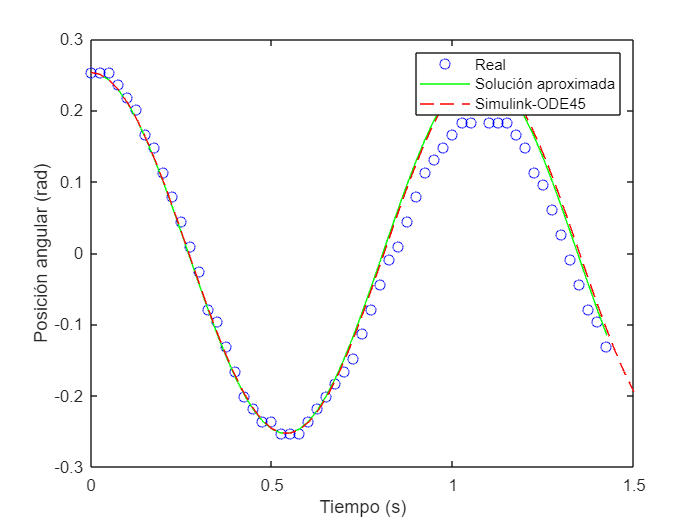

plot(tiempo,f_theta,'bo',tiempo,F(x,tiempo),'g',t,wave,'--r')
legend('Real','Solución aproximada','Simulink-ODE45')
xlabel('Tiempo (s)');
ylabel('Posición angular (rad)');

Velocidad angular ángulo pequeño

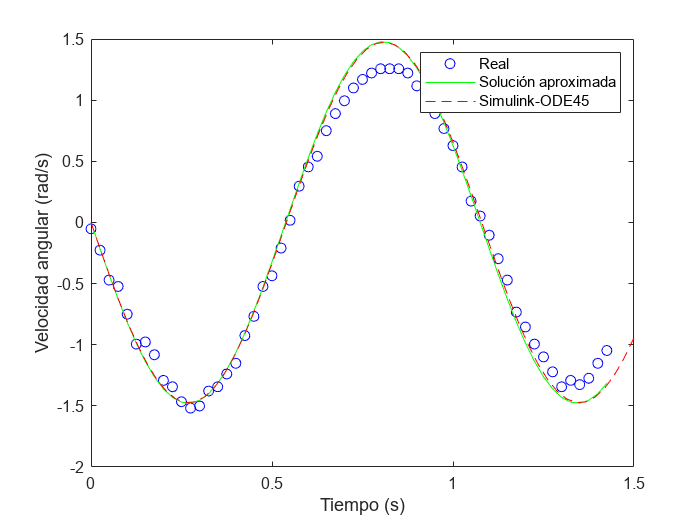

figure()
plot(tiempo,Rapidez,'bo',tiempo,V,'g',t,vel_ang,'--r')
legend('Real','Solución aproximada','Simulink-ODE45')
xlabel('Tiempo (s)');
ylabel('Velocidad angular (rad/s)');

Error 

% Posición
error_absoluto_aprox = abs(((f_theta - F(x,tiempo))/f_theta)*100);
error_mean_aprox = mean(error_absoluto_aprox,'all')

error_mean_aprox = 0.1805

error_absoluto_sim = abs(((f_theta - wave)/f_theta)*100);
error_mean_sim = mean(error_absoluto_sim,'all')

error_mean_sim = 0.2907

% Velocidad
error_absoluto_aprox_vel = abs(((Rapidez - V)/Rapidez)*100);
error_mean_aprox_vel = mean(error_absoluto_aprox_vel,'all')

error_mean_aprox_vel = 0.1244

error_absoluto_sim_vel = abs(((Rapidez - vel_ang)/Rapidez)*100);
error_mean_sim_vel = mean(error_absoluto_sim,'all')

error_mean_sim_vel = 0.2907

#### Solución ángulo grande

% Datos del ángulo grande
Tiempo = data_gr(6:61,"Var1");
tiempo = table2array(Tiempo);
t_0 = min(tiempo);
tiempo = tiempo - t_0;
F_angulo2 = data_gr(6:61,"Var2");
f_angulo2 = deg2rad(table2array(F_angulo2));
Rapidez2 = data_gr(6:61,"Var3");
rapidez2 = deg2rad(table2array(Rapidez2));

% Ángulo inicial grande
theta_0 = (max(f_angulo2) -  min(f_angulo2))/2;

%Corrimiento
f_theta = theta_0 + f_angulo2;

% Amplitud
theta_m = theta_0/sin(phi);

Solución mínimos cuadrados no lineales

F = @(wn,xdata)theta_m*(sin(wn(1)*xdata + phi));
x0 = [5];
[wn,resnorm,~,exitflag,output] = lsqcurvefit(F,x0,tiempo,f_theta);


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


V = (theta_m)*wn(1)*cos(wn(1)*tiempo + phi);

#### Solución mediante SIMULINK y ODE45

Ode = sim('gr_onda.slx');
t= Ode.gr_onda(:,1);
wave= Ode.gr_onda(:,2);
vel_ang = Ode.vel_gr(:,2);

Salida gráfica: comparación de la solución aproximada y la solución por ODE45 en relación a los datos experimentales

Posición angular ángulo grande

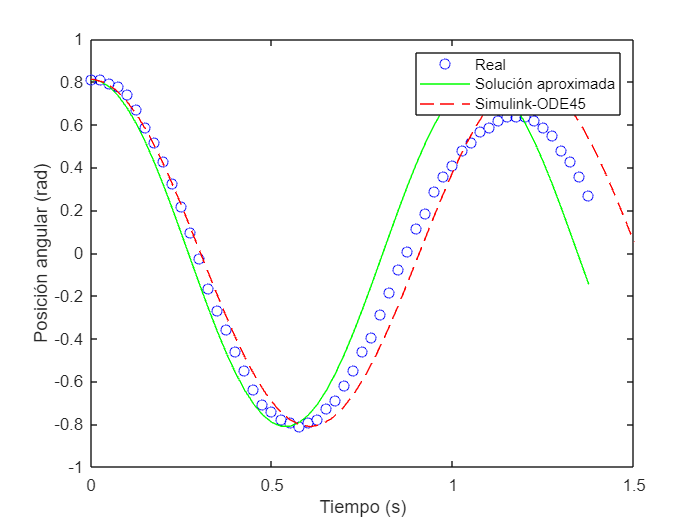

plot(tiempo,f_theta,'bo',tiempo,F(x,tiempo),'g',t,wave,'--r')
legend('Real','Solución aproximada','Simulink-ODE45')
xlabel('Tiempo (s)');
ylabel('Posición angular (rad)');

Velocidad angular ángulo grande

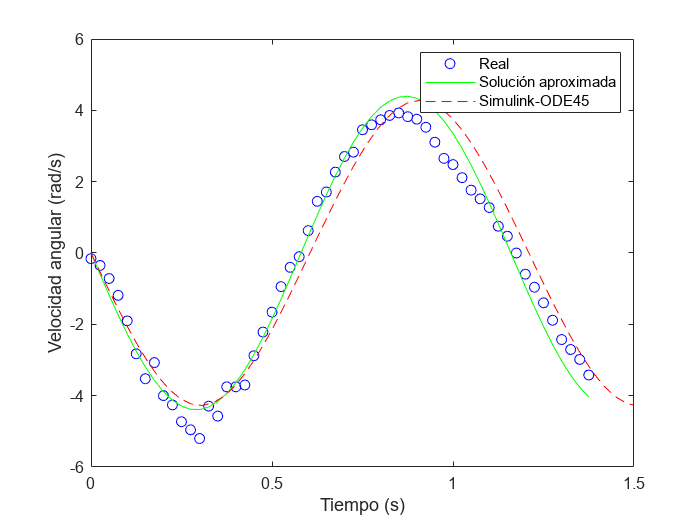

figure()
plot(tiempo,rapidez2,'bo',tiempo,V,'g',t,vel_ang,'--r')
legend('Real','Solución aproximada','Simulink-ODE45')
xlabel('Tiempo (s)');
ylabel('Velocidad angular (rad/s)');

Error

% Posición
error_absoluto_aprox = abs(((f_theta - F(x,tiempo))/f_theta)*100);
error_mean_aprox = mean(error_absoluto_aprox,'all')

error_mean_aprox = 0.3453


error_absoluto_sim = abs(((f_theta - wave)/f_theta)*100);
error_mean_sim = mean(error_absoluto_sim,'all')

error_mean_sim = 0.3302

% Velocidad
error_absoluto_aprox_vel = abs(((rapidez2 - V)/rapidez2)*100);
error_mean_aprox_vel = mean(error_absoluto_aprox_vel,'all')

error_mean_aprox_vel = 0.1340

error_absoluto_sim_vel = abs(((rapidez2 - vel_ang)/rapidez2)*100);
error_mean_sim_vel = mean(error_absoluto_sim,'all')

error_mean_sim_vel = 0.3302